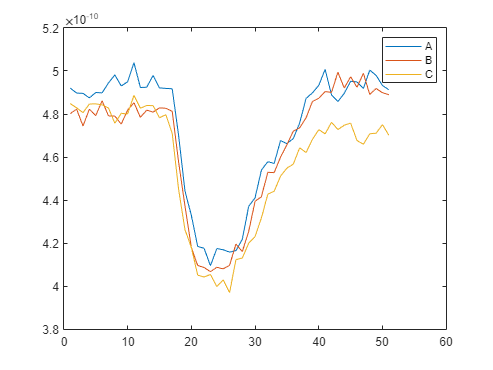

% this script is for reading the config_B set of reference wire scans
clear all;
close all;

filepath = 'C:\Users\Mog\Desktop\';

filename1 = 'Config_B_wire_reference_measurement_part_1';
filename2 = 'Config_B_wire_reference_measurement_part_2';

a_path = strcat(filepath, filename1);
b_path = strcat(filepath, filename2);

a = load(a_path);
b = load(b_path);

data_a = a.pressure;
data_b = b.pressure;

A = data_b(1:51);
B = fliplr(data_b(52:end));
C = data_a;

plot(A); hold on; plot(B); plot(C); hold off; legend('A', 'B', 'C');


A_index_1 = 17; A_index_2 = 40;
B_index_1 = 17; B_index_2 = 42;
C_index_1 = 16; C_index_2 = 40;

x_full = 1:length(A);

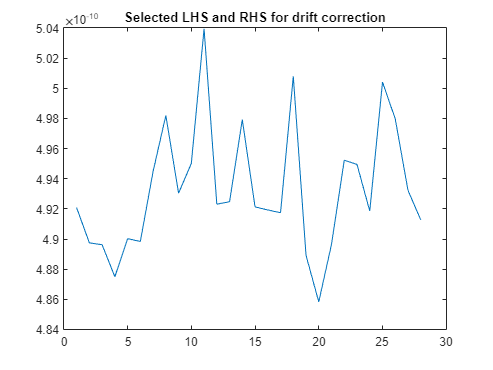

% DRIFT CORRECT A
%splitting the data up
A_1 = A( 1:A_index_1 );
A_2 = A( (A_index_1+1): A_index_2);
A_3 = A( (A_index_2+1):end);

%defining the splitting indexes
x_A1 = 1:A_index_1;
x_A2 = (A_index_1+1):A_index_2;
x_A3 = (A_index_2+1):length(A);

%selects the data applicable to drift correction
A_selected = [A_1, A_3];
x_A_selected = [x_A1, x_A3];

plot(A_selected); title('Selected LHS and RHS for drift correction');

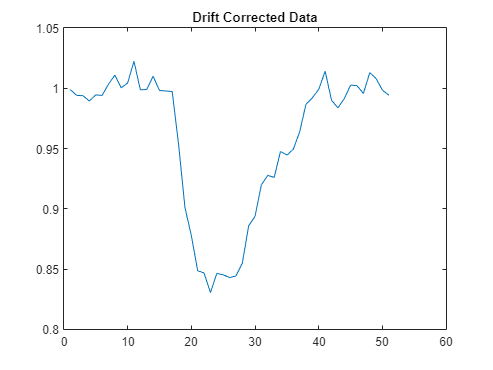


%generates the fitting parameters
[a b]=polyfit(x_A_selected, A_selected, 1);

%generates the full fitting for all indexes using above fitting parameters
fitmag=a(2)+a(1)*x_full;

A_corrected=(A./(fitmag));
plot(A_corrected); title('Drift Corrected Data');

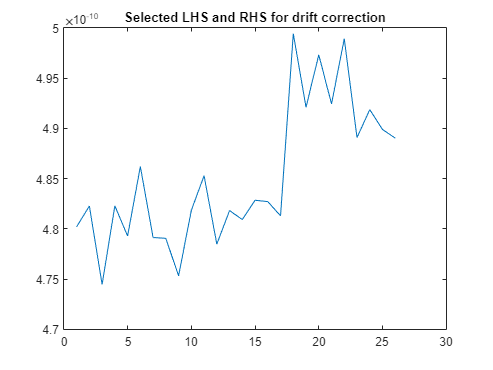

% DRIFT CORRECT B
%splitting the data up
B_1 = B( 1:B_index_1 );
B_2 = B( (B_index_1+1): B_index_2);
B_3 = B( (B_index_2+1):end);

%defining the splitting indexes
x_B1 = 1:B_index_1;
x_B2 = (B_index_1+1):B_index_2;
x_B3 = (B_index_2+1):length(B);

%selects the data applicable to drift correction
B_selected = [B_1, B_3];
x_B_selected = [x_B1, x_B3];

plot(B_selected); title('Selected LHS and RHS for drift correction');

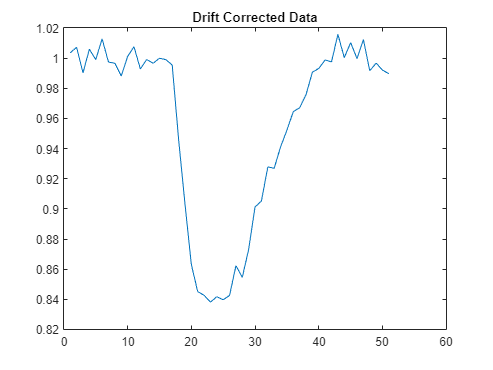


%generates the fitting parameters
[a b]=polyfit(x_B_selected, B_selected, 1);

%generates the full fitting for all indexes using above fitting parameters
fitmag=a(2)+a(1)*x_full;

B_corrected=(B./(fitmag));
plot(B_corrected); title('Drift Corrected Data');

% DRIFT CORRECT C
%splitting the data up
C_1 = C( 1:C_index_1 );
C_2 = C( (C_index_1+1): C_index_2);
C_3 = C( (C_index_2+1):end);

%defining the splitting indexes
x_C1 = 1:C_index_1;
x_C2 = (C_index_1+1):C_index_2;
x_C3 = (C_index_2+1):length(C);

%selects the data applicable to drift correction
C_selected = [C_1, C_3];
x_C_selected = [x_C1, x_C3];

plot(B_selected); title('Selected LHS and RHS for drift correction');

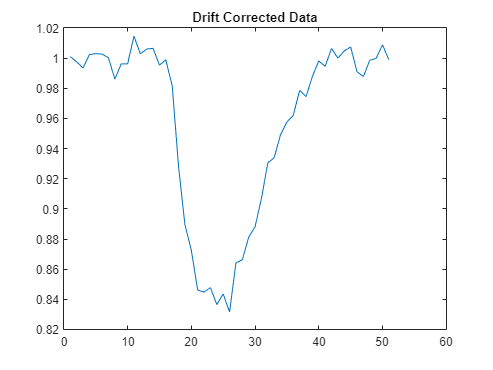


%generates the fitting parameters
[a b]=polyfit(x_C_selected, C_selected, 1);

%generates the full fitting for all indexes using above fitting parameters
fitmag=a(2)+a(1)*x_full;

C_corrected=(C./(fitmag));
plot(C_corrected); title('Drift Corrected Data');

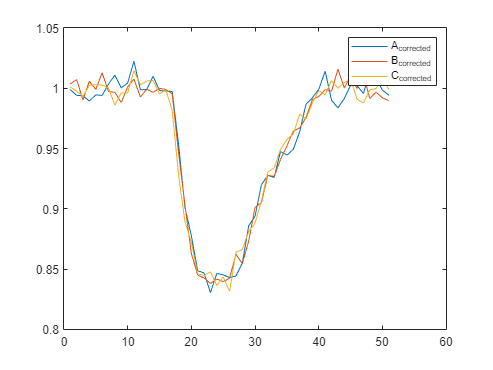

%plotting all drift corrected data
plot(A_corrected); hold on; plot(B_corrected); plot(C_corrected); legend('A_{corrected}', 'B_{corrected}', 'C_{corrected}'); hold off;

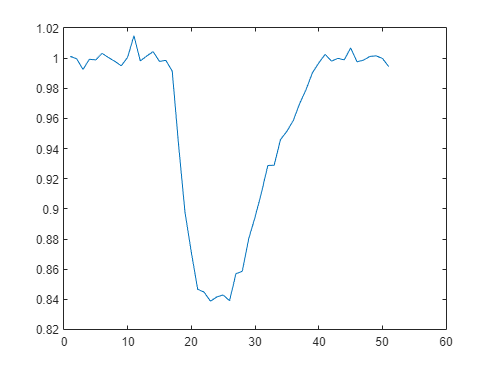

%Combined datasets
full_corrected = [ A_corrected' , B_corrected' , C_corrected' ];
mean_corrected = mean(full_corrected, 2);
plot(mean_corrected);

%x-axis discretisation
wire_scan_width = (100/25) * 0.635;
wire_scan_positions = linspace( -wire_scan_width/2 , wire_scan_width/2, length(mean_corrected) );

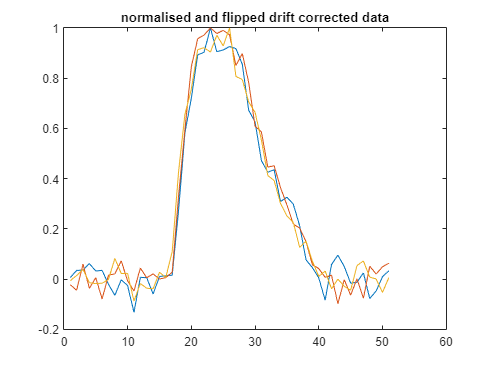

%flips and normalises the data
full_corrected = -full_corrected + 1;
full_norm = full_corrected ./ max(full_corrected);
plot(full_norm); title('normalised and flipped drift corrected data');


%fliplr dataset (since negative gyromagnetic ratio)
full_norm = flipud(full_norm);

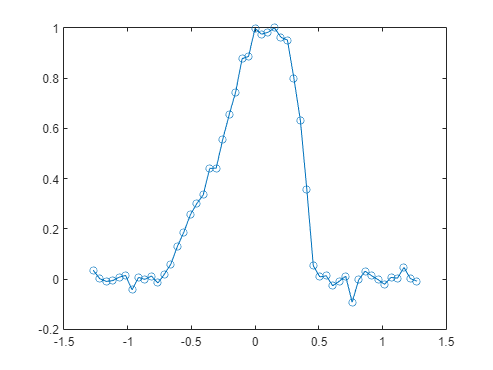

offset = 0.28;

%Calculates the mean and standard deviation of the datasets
mean_corrected = mean(full_norm, 2);
mean_corrected = mean_corrected ./ max(mean_corrected);

plot(wire_scan_positions, mean_corrected, 'o-');

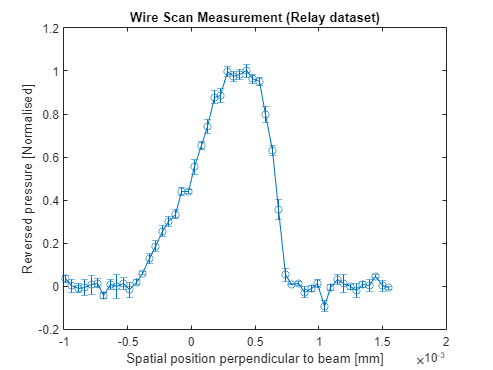

stdev_corrected = std(full_norm');
error_full = stdev_corrected / sqrt(3);

errorbar((wire_scan_positions + offset)*1e-3, mean_corrected, error_full, 'o-');
title('Wire Scan Measurement (Config_B dataset)');
xlabel('Spatial position perpendicular to beam [mm]');
ylabel('Reversed pressure [Normalised]');


% writematrix([((wire_scan_positions + offset)*1e-3)', mean_corrected], 'wire_scan_config_B.txt');